# Part(II) Modeling Tensile Stress-Strain Response of Mild Steel Reinforcement

## Question 1. Plot the stress-strain data in both engineering and true coordinate systems

### Part (i)

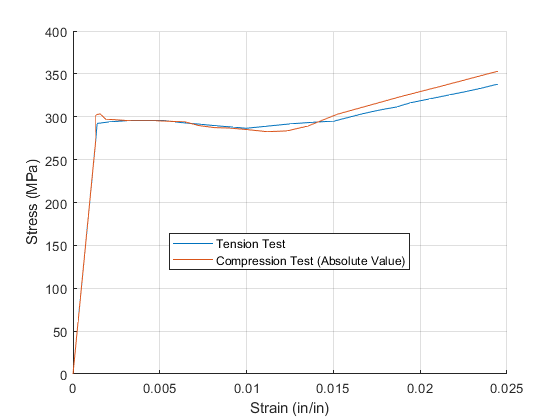

% This portion is to examine only the data before strain hardening
clc; clear; close all;
range_ = [0, 0.025]; % data range 
[compressive_strain, compressive_stress, tensile_strain, tensile_stress] = get_data_for_range(range_); % gets data; see functions

figure(1); hold on; grid on;  % Plot
plot(tensile_strain,tensile_stress,"DisplayName","Tension Test");
plot(-compressive_strain,-compressive_stress,"DisplayName","Compression Test (Absolute Value)"); % Note: include a negative sign
legend("Location","best"); ylabel("Stress (MPa)"); xlabel("Strain (in/in)"); %
print_figure('11b') % Save figure as pdf

tensile = [tensile_strain, tensile_stress];
compressive =- [compressive_strain,compressive_stress];
DiscreteFrechetDist(compressive,tensile)

ans = 17.3740

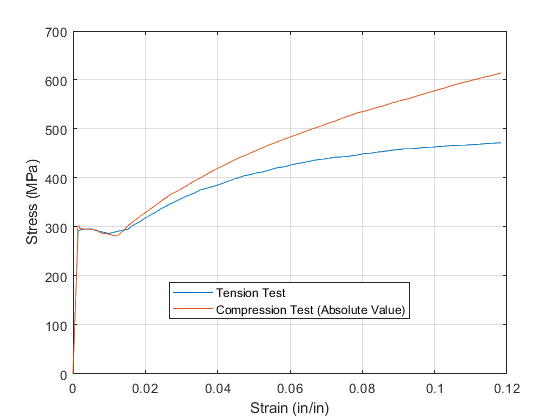

% This portion is asked for the homework.
close all; % New plot
figure(2); hold on; grid on; box on; % Choice
range_ = [0, 0.12]; % Strain range
[compressive_strain, compressive_stress, tensile_strain, tensile_stress] = get_data_for_range(range_); % Get data
plot(tensile_strain,tensile_stress,"DisplayName","Tension Test"); %Plot
plot(-compressive_strain,-compressive_stress,"DisplayName","Compression Test (Absolute Value)"); % Note negative values
legend("Location","best"); ylabel("Stress (MPa)"); xlabel("Strain (in/in)"); % Plot things
print_figure(11); % Save fig as pdf

tensile = [tensile_strain, tensile_stress];
compressive =- [compressive_strain,compressive_stress];
DiscreteFrechetDist(compressive,tensile)

ans = 142.5810

Transform the stress-strain relationship from engineering to true coordinate system and plot the true stress-strain tensile and compressive relationships in absolute values.

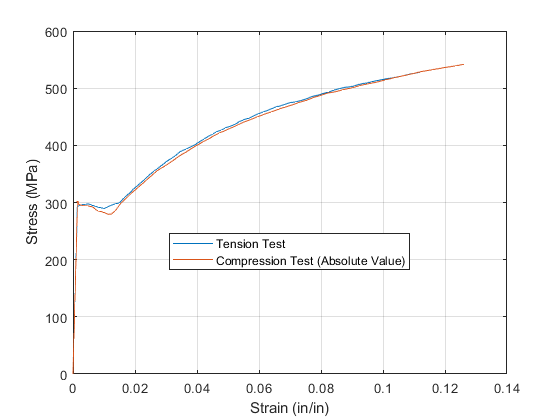

% This section is the plot for true stress-strain
close all; % New plot
figure(3); hold on; grid on; box on;
range_ = [0, 0.12]; % Defines the range of strain data

[compressive_strain, compressive_stress, tensile_strain, tensile_stress] = get_data_for_range(range_); % Grabs the data from excel

natural_tensile_stress = tensile_stress.*(1+tensile_strain); % stress' = stress * (1 + strain) 
natural_tensile_strain = log(1 + tensile_strain); % strain' = ln(1 + strain)

natural_compressive_stress = - compressive_stress.*(1 + compressive_strain); % stress' = stress * (1 + strain) 
natural_compressive_strain = -log(1 + compressive_strain); % strain = ln(1 + strain)

plot(natural_tensile_strain,natural_tensile_stress,"DisplayName","Tension Test"); % Plot
plot(natural_compressive_strain,natural_compressive_stress,"DisplayName","Compression Test (Absolute Value)"); % Plot
legend("Location","best"); ylabel("Stress (MPa)"); xlabel("Strain (in/in)"); % Plot
print_figure(12); % Save fig as pdf

tensile = [natural_tensile_strain, natural_tensile_stress];
compressive = [natural_compressive_strain,natural_compressive_stress];
DiscreteFrechetDist(compressive,tensile)

ans = 16.7994

function [compressive_strain, compressive_stress, tensile_strain, tensile_stress] = get_data_for_range(range_)
    opts = spreadsheetImportOptions("NumVariables", 2);
    % Specify sheet and range
    opts.Sheet = "Compressive";
    opts.DataRange = "B3:C99";
    % Specify column names and types
    opts.VariableNames = ["Strain", "Stress"];
    opts.VariableTypes = ["double", "double"];
    % Import the data
    tbl = readtable("C:\Users\Louis Lin\Workspace\Academic\UCSD\SE 211\Homework\HW 1\data\Monotonic tensile compressive on machined coupons.xlsx", opts, "UseExcel", false);
    strain_range = and(tbl.Strain <= -range_(1), tbl.Strain >= -range_(2)); % Selects a data range as specified
    compressive_strain = tbl.Strain(strain_range);
    compressive_stress = tbl.Stress(strain_range);
    
    opts = spreadsheetImportOptions("NumVariables", 2);
    % Specify sheet and range
    opts.Sheet = "Tensile";
    opts.DataRange = "B4:C128";
    % Specify column names and types
    opts.VariableNames = ["Strain", "Stress"];
    opts.VariableTypes = ["double", "double"];
    % Import the data
    tbl = readtable("C:\Users\Louis Lin\Workspace\Academic\UCSD\SE 211\Homework\HW 1\data\Monotonic tensile compressive on machined coupons.xlsx", opts, "UseExcel", false);
    strain_range = and(tbl.Strain >= range_(1), tbl.Strain<=range_(2)); % Selects a data range as specified
    tensile_strain = tbl.Strain(strain_range);
    tensile_stress = tbl.Stress(strain_range);
end

function print_figure(no)
    orient(gcf,'landscape');
    folder = '..\figures\';
    name = 'Figure' +string(no);
    print(folder+name,'-djpeg','-PMicrosoft Print to PDF','-r600','-painters')
    print(folder+name,'-dpdf','-fillpage','-PMicrosoft Print to PDF','-r600','-painters')
end

function [cm, cSq] = DiscreteFrechetDist(P,Q,dfcn)
% Calculates the discrete Frechet distance between curves P and Q
%
% [cm, cSq] = DiscreteFrechetDist(P,Q)
% [cm, cSq] = DiscreteFrechetDist(...,dfcn)
%
% P and Q are two sets of points that define polygonal curves with rows of
% vertices (data points) and columns of dimensionality. The points along
% the curves are taken to be in the order as they appear in P and Q.
%
% Returned in cm is the discrete Frechet distance, aka the coupling
% measure, which is zero when P equals Q and grows positively as the curves
% become more dissimilar.
%
% The optional dfcn argument allows the user to specify a function with
% which to calculate distance between points in P and Q. If not provided,
% the L2 norm is used.
%
% The secondary output, cSq, is the coupling sequence, that is, the
% sequence of steps along each curve that must be followed to achieve the
% minimum coupling distance, cm. The output is returned in the form of a
% matrix with column 1 being the index of each point in P and column 2
% being the index of each point in Q. (NOTE: the coupling sequence is not
% unique in general)
%
% Explanation:
% The Frechet distance is a measure of similarity between to curves, P and
% Q. It is defined as the minimum cord-length sufficient to join a point
% traveling forward along P and one traveling forward along Q, although the
% rate of travel for either point may not necessarily be uniform.
%
% The Frechet distance, FD, is not in general computable for any given
% continuous P and Q. However, the discrete Frechet Distance, also called
% the coupling measure, cm, is a metric that acts on the endpoints of
% curves represented as polygonal chains. The magnitude of the coupling
% measure is bounded by FD plus the length of the longest segment in either
% P or Q,  and approaches FD in the limit of sampling P and Q.
%
% This function implements the algorithm to calculate discrete Frechet
% distance outlined in:
% T. Eiter and H. Mannila. Computing discrete Frechet distance. Technical
% Report 94/64, Christian Doppler Laboratory, Vienna University of
% Technology, 1994.
% 
%
%
% EXAMPLE:
% % create data
% t = 0:pi/8:2*pi;
% y = linspace(1,3,6);
% P = [(2:7)' y']+0.3.*randn(6,2);
% Q = [t' sin(t')]+2+0.3.*randn(length(t),2);
% [cm, cSq] = DiscreteFrechetDist(P,Q);
% % plot result
% figure
% plot(Q(:,1),Q(:,2),'o-r','linewidth',3,'markerfacecolor','r')
% hold on
% plot(P(:,1),P(:,2),'o-b','linewidth',3,'markerfacecolor','b')
% title(['Discrete Frechet Distance of curves P and Q: ' num2str(cm)])
% legend('Q','P','location','best')
% line([2 cm+2],[0.5 0.5],'color','m','linewidth',2)
% text(2,0.4,'dFD length')
% for i=1:length(cSq)
%   line([P(cSq(i,1),1) Q(cSq(i,2),1)],...
%        [P(cSq(i,1),2) Q(cSq(i,2),2)],...
%        'color',[0 0 0]+(i/length(cSq)/1.35));
% end
% axis equal
% % display the coupling sequence along with each distance between points
% disp([cSq sqrt(sum((P(cSq(:,1),:) - Q(cSq(:,2),:)).^2,2))])
%
%
% 
% %%% ZCD June 2011 %%%
% %%% edits ZCD May 2013: 1) remove excess arguments to internal functions
% and persistence for speed, 2) added example, 3) allowed for user defined
% distance function, 4) added aditional output option for coupling sequence
%
% size of the data curves
sP = size(P);
sQ = size(Q);
% check validity of inputs
if sP(2)~=sQ(2)
    error('Curves P and Q must be of the same dimension')
elseif sP(1)==0
    cm = 0;
    return;
end
% initialize CA to a matrix of -1s
CA = ones(sP(1),sQ(1)).*-1;
% distance function
if nargin==2
    dfcn = @(u,v) sqrt(sum( (u-v).^2 ));
end
% final coupling measure value
cm = c(sP(1),sQ(1));
% obtain coupling measure via backtracking procedure
if nargout==2
    cSq = zeros(sQ(1)+sP(1)+1,2);    % coupling sequence
    CApad = [ones(1,sQ(1)+1)*inf; [ones(sP(1),1)*inf CA]];  % pad CA
    Pi=sP(1)+1; Qi=sQ(1)+1; count=1;  % counting variables
    while Pi~=2 || Qi~=2
        % step down CA gradient
        [v,ix] = min([CApad(Pi-1,Qi) CApad(Pi-1,Qi-1) CApad(Pi,Qi-1)]);
        if ix==1
            cSq(count,:) = [Pi-1 Qi];
            Pi=Pi-1;
        elseif ix==2
            cSq(count,:) = [Pi-1 Qi-1];
            Pi=Pi-1; Qi=Qi-1;
        elseif ix==3
            cSq(count,:) = [Pi Qi-1];
            Qi=Qi-1;
        end
        count=count+1;
    end
    % format output: remove extra zeroes, reverse order, subtract off
    % padding value, and add in the last point
    cSq = [flipud(cSq(1:find(cSq(:,1)==0,1,'first')-1,:))-1; sP(1) sQ(1)];
end
% debug
% assignin('base','CAw',CA)
function CAij = c(i,j)
    % coupling search function
    if CA(i,j)>-1
        % don't update CA in this case
        CAij = CA(i,j);
    elseif i==1 && j==1
        CA(i,j) = dfcn(P(1,:),Q(1,:));     % update the CA permanent
        CAij = CA(i,j);                    % set the current relevant value
    elseif i>1 && j==1
        CA(i,j) = max( c(i-1,1), dfcn(P(i,:),Q(1,:)) );
        CAij = CA(i,j);
    elseif i==1 && j>1
        CA(i,j) = max( c(1,j-1), dfcn(P(1,:),Q(j,:)) );
        CAij = CA(i,j);
    elseif i>1 && j>1
        CA(i,j) = max( min([c(i-1,j), c(i-1,j-1), c(i,j-1)]),...
            dfcn(P(i,:),Q(j,:)) );
        CAij = CA(i,j);
    else
        CA(i,j) = inf;
    end
end     % end function, c
end     % end main function